Given $f\left(x\right)=\left\lbrace \begin{array}{cc}
-1 & -\pi \le x<0\\
1 & 0\le x\le \pi \;
\end{array}\right.$

syms x;
T = 2*pi;
w = 2*pi/T;
k = 10;
f1 = -1;
f2 = 1;
n = -k:k;
cn = (int(f1 * exp(-i*n*w*x), x, -pi, 0) ...
    + int(f2 * exp(-i*n*w*x), x, 0, pi))/T

$$cn = \begin{array}{l} \left(\begin{array}{ccccccccccccccccccccc} 0 & \sigma_{1} & 0 & \sigma_{2} & 0 & \sigma_{3} & 0 & \sigma_{4} & 0 & \frac{2\,\mathrm{i}}{\pi } & 0 & -\frac{2\,\mathrm{i}}{\pi } & 0 & -\sigma_{4} & 0 & -\sigma_{3} & 0 & -\sigma_{2} & 0 & -\sigma_{1} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,\mathrm{i}}{9\,\pi }\\ \sigma_{2}=\frac{2\,\mathrm{i}}{7\,\pi }\\ \sigma_{3}=\frac{2\,\mathrm{i}}{5\,\pi }\\ \sigma_{4}=\frac{2\,\mathrm{i}}{3\,\pi } \end{array}$$

CFS = sum(cn.*exp(i*n*w*x));
CFS = simplify(CFS)

$$CFS = \frac{2\,{\mathrm{e}}^{-9\,x\,\mathrm{i}}\,\left(45\,{\mathrm{e}}^{2\,x\,\mathrm{i}}\,\mathrm{i}+63\,{\mathrm{e}}^{4\,x\,\mathrm{i}}\,\mathrm{i}+105\,{\mathrm{e}}^{6\,x\,\mathrm{i}}\,\mathrm{i}+315\,{\mathrm{e}}^{8\,x\,\mathrm{i}}\,\mathrm{i}-315\,{\mathrm{e}}^{10\,x\,\mathrm{i}}\,\mathrm{i}-105\,{\mathrm{e}}^{12\,x\,\mathrm{i}}\,\mathrm{i}-63\,{\mathrm{e}}^{14\,x\,\mathrm{i}}\,\mathrm{i}-45\,{\mathrm{e}}^{16\,x\,\mathrm{i}}\,\mathrm{i}-35\,{\mathrm{e}}^{18\,x\,\mathrm{i}}\,\mathrm{i}+35\,\mathrm{i}\right)}{315\,\pi }$$

x = linspace(-pi, 5*pi, 500);
y = eval(CFS);
plot(real(x), y, 'r');

hold on;
f = @(x) -1.*(-pi<=x & x <0)+1.*(0<=x & x<=pi)

f = function_handle with value:
    @(x)-1.*(-pi<=x&x<0)+1.*(0<=x&x<=pi)


x1 = linspace(-pi, pi, 500);
y2 = f(x1);
ry2 = repmat(y2, 1, 3);
rx1 = linspace(-pi, 5*pi, length(ry2))

rx1 =    -3.1416   -3.1290   -3.1164   -3.1039   -3.0913   -3.0787   -3.0661   -3.0536   -3.0410   -3.0284   -3.0158   -3.0033   -2.9907   -2.9781   -2.9655   -2.9530   -2.9404   -2.9278   -2.9152   -2.9027   -2.8901   -2.8775   -2.8649   -2.8524   -2.8398   -2.8272   -2.8146   -2.8021   -2.7895   -2.7769   -2.7644   -2.7518   -2.7392   -2.7266   -2.7141   -2.7015   -2.6889   -2.6763   -2.6638   -2.6512   -2.6386   -2.6260   -2.6135   -2.6009   -2.5883   -2.5757   -2.5632   -2.5506   -2.5380   -2.5254


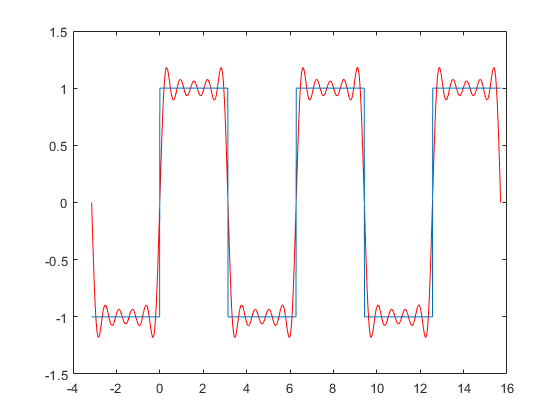

plot(rx1, ry2)